# ** GRN Project 1**

Consider the simplified Guido-Collins system with an activator transcription factor and an inhibitor transcription factor. 

You may use the code `GuidoCollins_simplified01.m` Section 2.3

# HW1 PART 1

Assume the concentration of inhibitor is fixed at 10uM.  

Plot the steady-state amount of Protein as a function of the activator concentration, but make the axis showing concentration of activator a logarithmic axis.

What is the concentration of activator that results in half its maximal effect? This is called the EC50 of the activator.

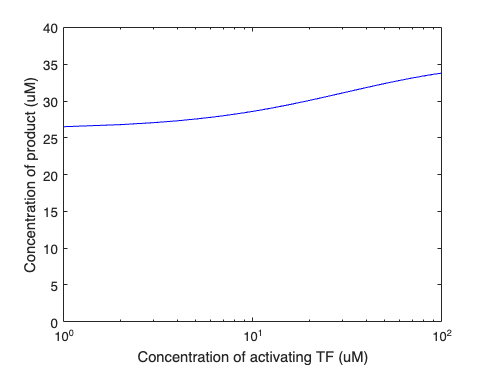

%set(gca,'xscale','log') % uncomment to make a log plot

%% 2.4 Positive feedback

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;
    
    gamma_p2 = 0.1;
    
    I = 10; 
    C = paramArray(iParam); % external activatory transcription factor 
    
    M =@(pb,t) [-kon*(C+pb)-kon*I,   +koff*I           , koff       ,       0;
                           +kon*I,   -koff*I-kon*(C+pb),           0,   +koff;
                +kon*(C+pb)      ,                    0, -koff-kon*I,   +koff;
                        0        ,           kon*(C+pb),       kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    dmdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_m(p0,pr,pa,par)     - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_p*m - delta_p*p;
    
    dmbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_m(p0,pr,pa,par)   - delta_m*mb;
    dpbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_p2*mb - delta_p*pb;
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
               dmdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
               dpdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end


figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') 
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);
set(gca,'xscale','log')


halfMaxvalue = (min(g_storage) + max(g_storage)) / 2

halfMaxvalue = 30.0103

interp1(g_storage,paramArray,halfMaxvalue)

ans = 19.3293

# HW1 PART 2

Assume the concentration of activator is fixed at 10uM. 

Plot the steady-state amount of Protein as a function of the inhibitor concentration.

What is the concentration of inhibitor that results in half its maximal inhibition? This is called the IC50 of the inhibitor. 

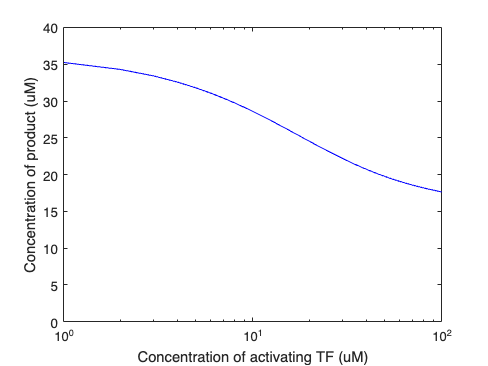

%set(gca,'xscale','log') % uncomment to make a log plot

%% 2.4 Positive feedback

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;
    
    gamma_p2 = 0.1;
    
    C = 10; 
    I = paramArray(iParam); % external activatory transcription factor 
    
    M =@(pb,t) [-kon*(C+pb)-kon*I,   +koff*I           , koff       ,       0;
                           +kon*I,   -koff*I-kon*(C+pb),           0,   +koff;
                +kon*(C+pb)      ,                    0, -koff-kon*I,   +koff;
                        0        ,           kon*(C+pb),       kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    dmdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_m(p0,pr,pa,par)     - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_p*m - delta_p*p;
    
    dmbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_m(p0,pr,pa,par)   - delta_m*mb;
    dpbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_p2*mb - delta_p*pb;
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
               dmdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
               dpdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') 
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);
set(gca,'xscale','log') 


halfMaxvalue = (min(g_storage) + max(g_storage)) / 2

halfMaxvalue = 26.9562

interp1(g_storage,paramArray,halfMaxvalue)

ans = 13.3500